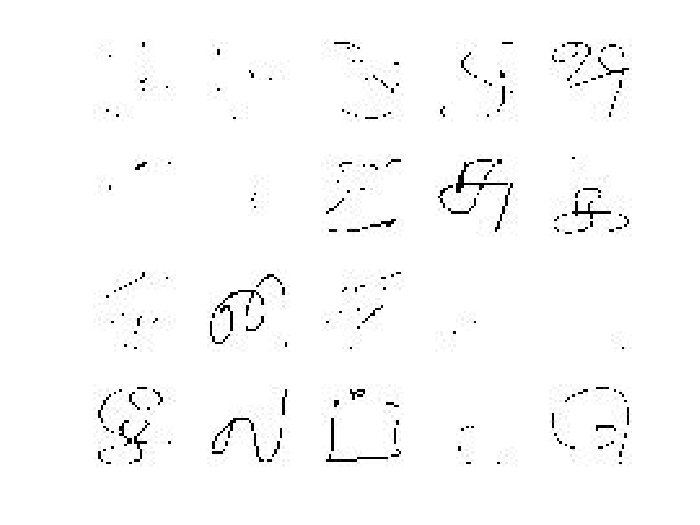

dataset_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Dataset\hpl\hpl_final\hpl_final_jpg\');
imds = imageDatastore(dataset_path, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
perm = randperm(50683,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

labelCount = countEachLabel(imds)

labelCount = 155×2 table
    Label    Count
    _____    _____

     1        347 
     10       329 
     100      332 
     101      299 
     102      323 
     103      327 
     104      338 
     105      330 
     106      343 
     107      343 
     108      340 
     109      341 
     11       324 
     110      340 
     111      343 
     112      329 


img = readimage(imds,1);
size(img)

ans =     32    32


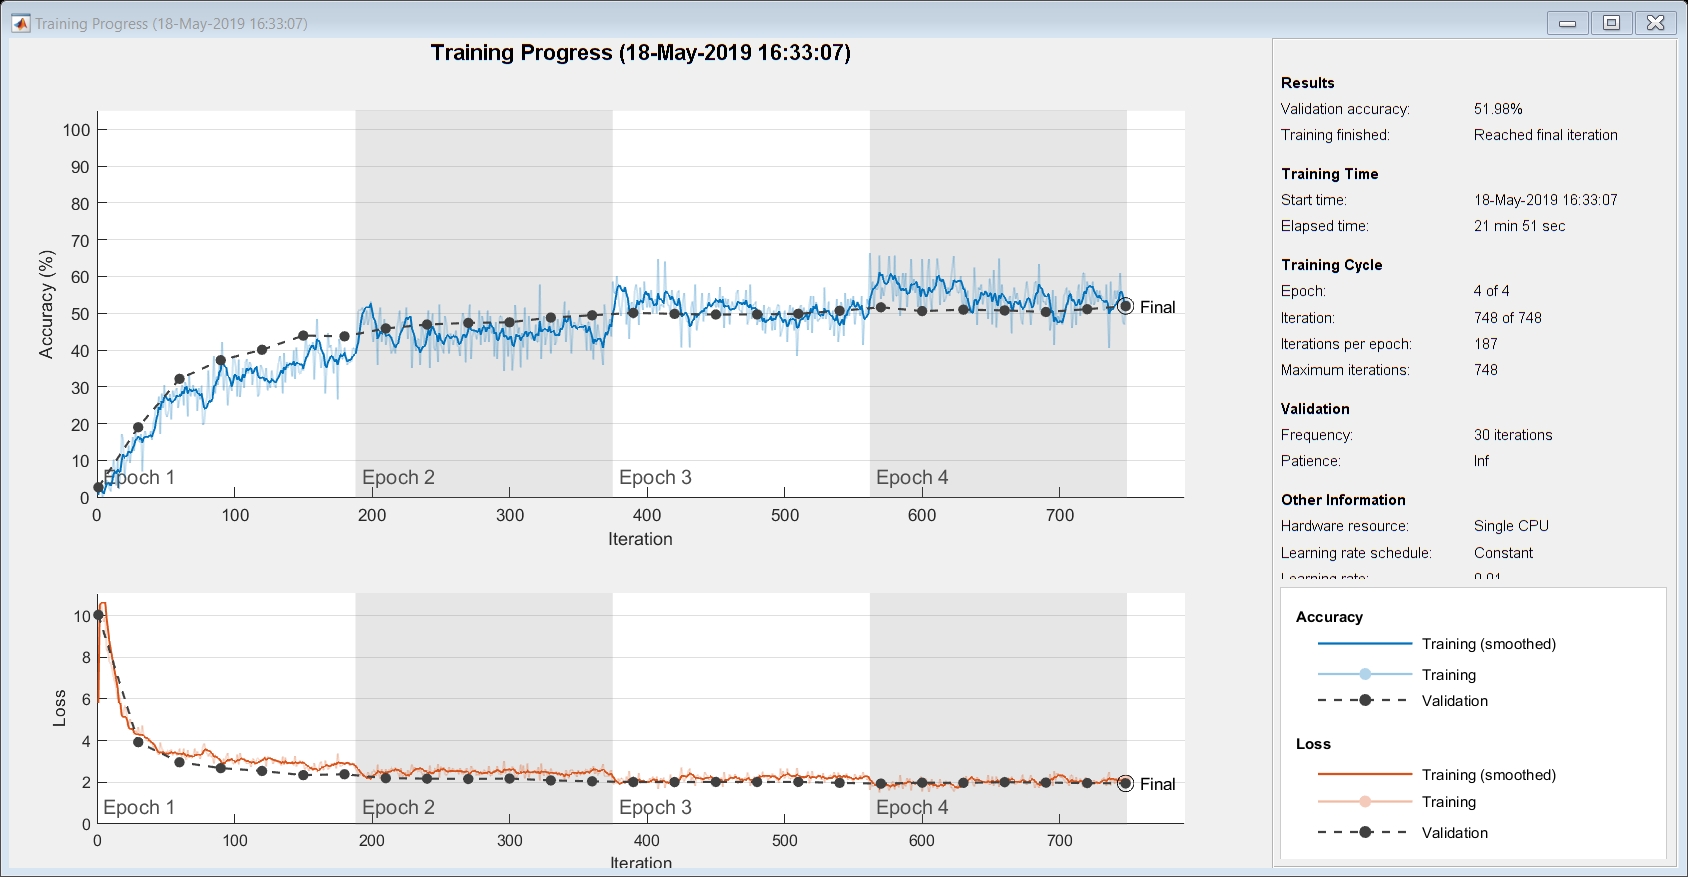

numTrainFiles = 155;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');
layers = [
    imageInputLayer([32 32 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(155)
    softmaxLayer
    classificationLayer];
options = trainingOptions('adam', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(imdsTrain,layers,options);

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.5198